# Numerical Analysis Project 2

Nathaniel Valla

format long
clear
clc

### Function used:

    newtons_div_dff(x_i,y_i,t): Takes two arrays of the same size and uses divided differences to find largangian polnoimal

    bezier_curves(x_i,y_i,y_d,t,h):Takes in two arrays of function values and the dervitative, point spacing, and test points

### Code Overview

    In this code three function are used to tests different methods of interpolation largangian, cubic splines and and Bezier curves. The largangian is found using newtons divided difference  method. The bezier curvers are found by finding the root of the cubic of the x at x_i and then plugged into the cubic of  y for y_i. The cubic splines are  found using the spline function from MatLab library. One is a Natural spline and the other is a clamped splines.

    After that the absolute errors are calculated for each tests function and interpolation methods. These are then grouped by method. This is so you can see how each method is able to interpolation different functions.

    Then the data provided is used to interpolate the headlamps, and the change in data is used to see how moving one data points effect the overall curve.

### Test cases:

        1. cos(x-0.2)

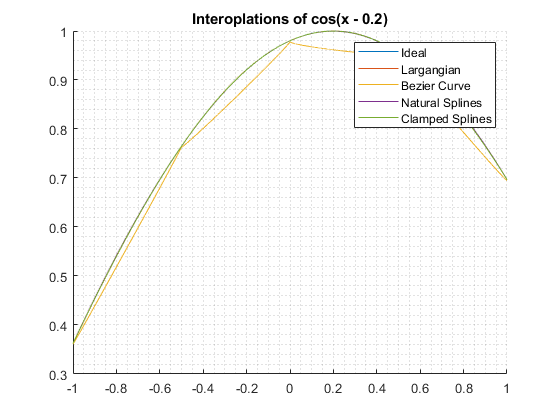

n = linspace(-1,1,5);
t = linspace(-1,1,10001);
h = n(2)-(1);

y_cos_shift = cos(n-0.2);
lag_cos_shift = newtons_div_dff(n,y_cos_shift,t);
y_cos_diff = -sin(n-0.2);
bezier_cos_shif = bezier_curves(n,y_cos_shift,y_cos_diff,t,h);
spline_cos = spline(n,y_cos_shift,t);
clamped_cos = spline(n,[y_cos_diff(1) y_cos_shift y_cos_diff(end)],t);

figure
hold on 
title('Interoplations of cos(x - 0.2)')

plot(t,cos(t-0.2))
plot(t,lag_cos_shift)
plot(t,bezier_cos_shif)
plot(t,spline_cos)
plot(t,clamped_cos)
legend(["Ideal","Largangian","Bezier Curve","Natural Splines","Clamped Splines"])
grid minor
hold off

        2. 1-x^2

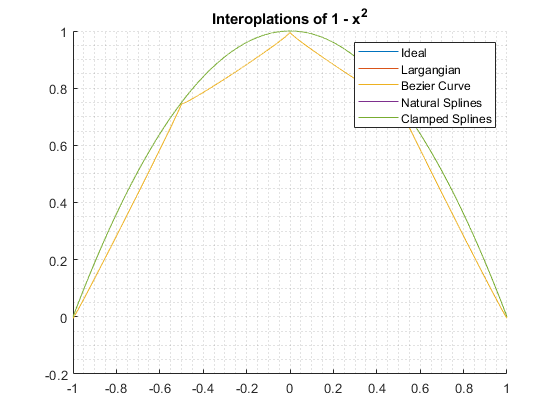

n = linspace(-1,1,5);
t = linspace(-1,1,10001);
h = n(2)-(1);

y_parabola = 1-n.^2;
lag_parabola = newtons_div_dff(n,y_parabola,t);
y_para_diff = -2*n;
bezier_para = bezier_curves(n,y_parabola,y_para_diff,t,h);
spline_para = spline(n,y_parabola,t);
clamped_para  = spline(n,[y_para_diff(1) y_parabola y_para_diff(end)],t);

figure
hold on 
title('Interoplations of 1 - x^2')
plot(t,1-t.^2)
plot(t,lag_parabola)
plot(t,bezier_para)
plot(t,spline_para)
plot(t,clamped_para)
legend(["Ideal","Largangian","Bezier Curve","Natural Splines","Clamped Splines"])
grid minor
hold off

        3. sqrt(5-x^2)

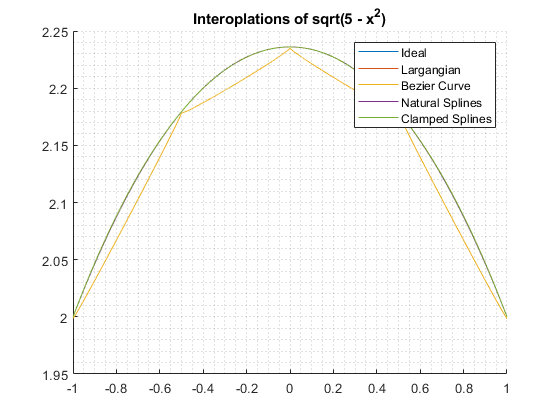

n = linspace(-1,1,5);
t = linspace(-1,1,10001);
h = n(2)-(1);

y_sqrt = sqrt(5-n.^2);
lag_sqrt = newtons_div_dff(n,y_sqrt,t);
y_sqrt_diff = (-n)./((5-n.^2).^(1/2));
bezier_sqrt = bezier_curves(n,y_sqrt,y_sqrt_diff,t,h);
spline_sqrt = spline(n,y_sqrt,t);
clamped_sqrt  = spline(n,[y_sqrt_diff(1) y_sqrt y_sqrt_diff(end)],t);

figure
hold on 
title('Interoplations of sqrt(5 - x^2)')
plot(t,sqrt(5-t.^2))
plot(t,lag_sqrt)
plot(t,bezier_sqrt)
plot(t,spline_sqrt)
plot(t,clamped_sqrt)
legend(["Ideal","Largangian","Bezier Curve","Natural Splines","Clamped Splines"])
grid minor
hold off

    In all three test case the Bezier curves are visually the least useful in interpolating. The other three methods it is harder to tell since the over lap pretty well.

### Methods Error:

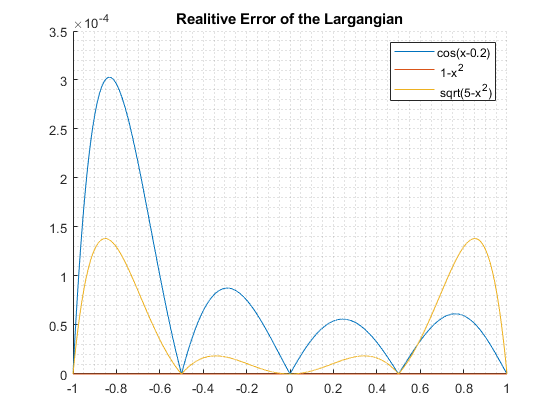

figure
hold on 
title('Realitive Error of the Largangian')
plot(t,abs(lag_cos_shift - cos(t-0.2)))
plot(t,abs(lag_parabola -(1-t.^2)))
plot(t,abs(lag_sqrt - sqrt(5-t.^2)))
legend(["cos(x-0.2)"," 1-x^2"," sqrt(5-x^2)"])
grid minor
hold off

    In cos(x-0.2) and sqrt(5-x^2) test senerio the largangian realtively well on about the scale of 10^-4 and the 1-x^2 sit at 10^-16. This is to be expected since the larganian is by defination the lowest order polynimial to fit through all point so actual polynomial is found.  The error that is achived is down to machine error.

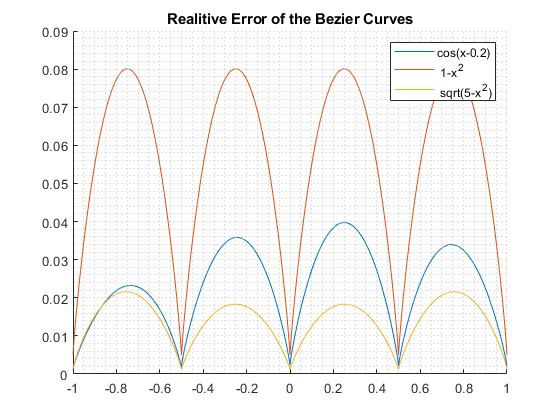

figure
hold on
title('Realitive Error of the Bezier Curves')
plot(t,abs(bezier_cos_shif - cos(t-0.2)))
plot(t,abs(bezier_para -(1-t.^2)))
plot(t,abs(bezier_sqrt - (sqrt(5-t.^2))))
legend(["cos(x-0.2)"," 1-x^2"," sqrt(5-x^2)"])
grid minor
hold off

      In all three cases the bezier curves performed bad with the error in scale 10^-1.

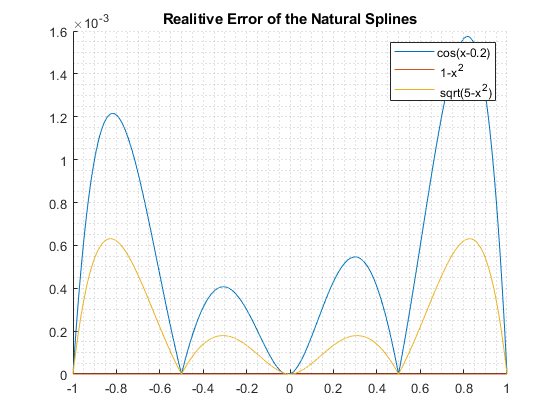

figure
hold on
title('Realitive Error of the Natural Splines')
plot(t,abs(spline_cos - cos(t-0.2)))
plot(t,abs(spline_para -(1-t.^2)))
plot(t,abs(spline_sqrt- (sqrt(5-t.^2))))
legend(["cos(x-0.2)"," 1-x^2"," sqrt(5-x^2)"])
grid minor
hold off

     In cos(x-0.2) and sqrt(5-x^2) test senerio the Natural Splines realtively well on about the scale of 10^-3. The polynomial is approxmated really well since it using polynomials to aproximate it. 

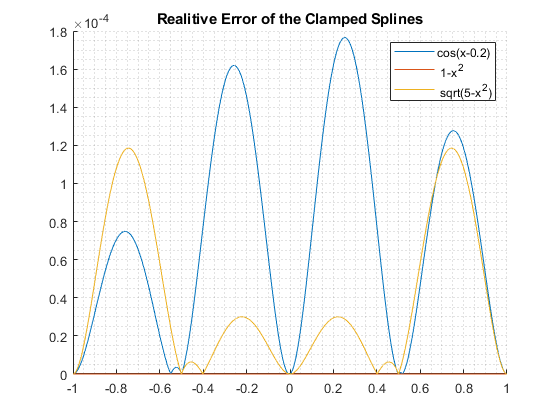

figure
hold on
title('Realitive Error of the Clamped Splines')
plot(t,abs(clamped_cos - cos(t-0.2)))
plot(t,abs(clamped_para -(1-t.^2)))
plot(t,abs(clamped_sqrt- (sqrt(5-t.^2))))
legend(["cos(x-0.2)"," 1-x^2"," sqrt(5-x^2)"])
grid minor
hold off

     In cos(x-0.2) and sqrt(5-x^2) test senerio theClamped Splines realtively well on about the scale of 10^-4. it actually does better then the larganian because it take the derviates into account. The polynomial is again approxmated really well since it using polynomials to aproximate it. 

### Test Points

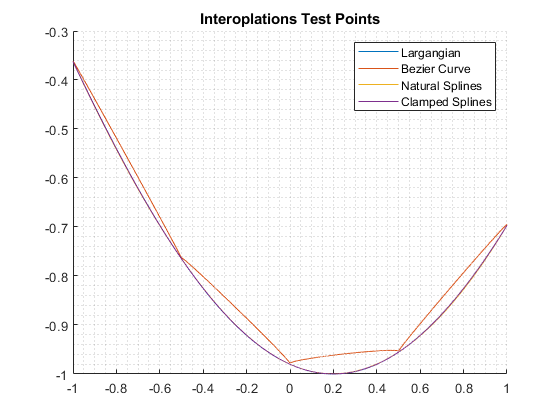

n = linspace(-1,1,5);
t = linspace(-1,1,10001);
h = n(2)-(1);

x  = n;
y  = [-0.36236,-0.76484,-0.98007,-0.95534,-0.69671];
yd = [-0.93204,-0.64422,-0.19867, 0.29552, 0.717356];

Largangian = newtons_div_dff(x,y,t);
bezier     = bezier_curves(x,y,yd,t,h);
spline1    = spline(x,y,t);
clamped    = spline(x,[yd(1) y yd(end)],t);

figure
hold on 
title('Interoplations Test Points')
plot(t,Largangian)
plot(t,bezier)
plot(t,spline1)
plot(t,clamped)
legend(["Largangian","Bezier Curve","Natural Splines","Clamped Splines"])
grid minor
hold off

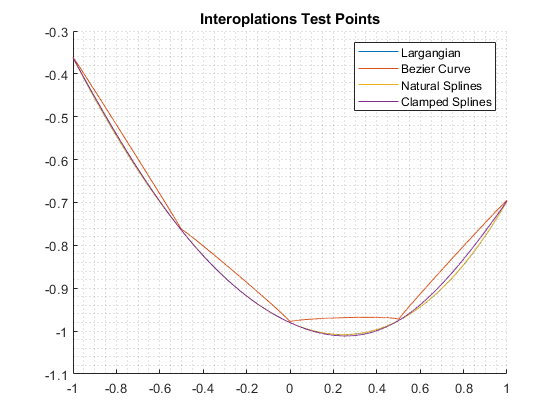

Current plot released


y1  = [-0.36236,-0.76484,-0.98007,-0.97534,-0.69671];
yd1 = [-0.93204,-0.64422,-0.19867, 0.32, 0.717356];

Largangian1 = newtons_div_dff(x,y1,t);
bezier1     = bezier_curves(x,y1,yd1,t,h);
spline2    = spline(x,y1,t);
clamped1    = spline(x,[yd1(1) y1 yd1(end)],t);

figure
hold on 
title('Interoplations Test Points')
plot(t,Largangian1)
plot(t,bezier1)
plot(t,spline2)
plot(t,clamped1)
legend(["Largangian","Bezier Curve","Natural Splines","Clamped Splines"])
grid minor
hold

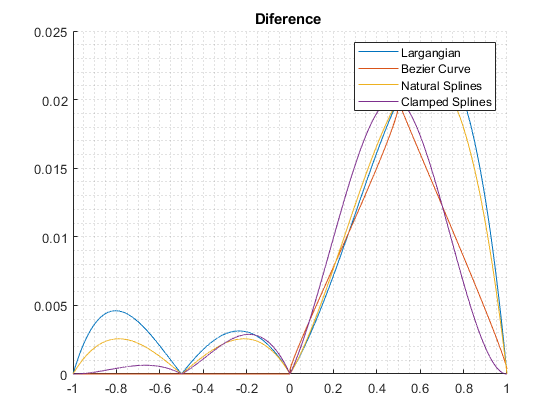

Current plot released



figure
hold on 
title('Diference ')
plot(t,abs(Largangian1 - Largangian))
plot(t,abs(bezier1 -bezier))
plot(t,abs(spline2 -spline1))
plot(t,abs(clamped1 - clamped))
legend(["Largangian","Bezier Curve","Natural Splines","Clamped Splines"])
grid minor
hold

    Between all four methods used when changing a single data point bezier changed the least and then followed by clamped splines. These makes sense since both take in the derviates into considerations and isolate the other changes quite well.

###  Conclusion

    The most usefully method for interpolation with these test is the clamped cubic splines since it interpolate the functions quite well in all senerios and isolates any large changes in data. Beizer curve are cleary the worst and that this is without  approxmating the derviates maybe if the test point are changed, using richard interpolation is probably need, but some date will have to be done using forward and backward difference since each of the beizer curzes needs to guide points. My process of the determinting the guide points is most likely needed to be reavaluated to better guide the functions since it purely guess and check.